Joey Lyon, February 2025

Linked GP emulation in Matlab based on papers by* Kyzyurova, Berger, and Wolpert* (2018), *Ming and Guillas* (2021) and *Dolksi, Spiller, and Minkoff* (2024)

***

These scripts rely on the RobustGaSp package. The package is included in the 'functions' folder with this code. You'll need to run the compile_cpp() funciton one, then you can comment it out with a %

%load other necessary packages (RobustGaSP)
addpath('functions'); 
%compile_cpp();

When generating or importing data, the data must be organized as follows: 

**Inputs**: Rows correspond to distinct parameter sets, columns correspond to different input parameters. 

**Outputs**: Rows correspond to distinct parameter sets, columns correspond to different output parameters. 


%load/generate data
rng(9)
N = 201; %
m = 300; 

%generate m x1 values between 0 and 2 using a space-filling design with a
%Latin hypercube
x1=lhsdesign(m,1);
x1 = x1*2;

%generate m x2 values between 0 and 2 using a space-filling design with a
%Latin hypercube
x2=lhsdesign(m,1);
x2 = x2*2;

Here we define the functions we will use for the outputs of this problem:


$$$w_1 = f_1(x_1, x_2) = \sin(x_1) + x_2^2$ \$$



$$$w_2 = f_2(x_1, x_2) = \sin(3x_1 \cos(\pi x_2))$$$



$$$g_1(w_1, w_2, z_1, z_2) = \cos(3z_2)\sin(3w_1) + \sin(3z_1)\cos(3w_2)$ \$$



$$$g_2(w_1, w_2, z_1, z_2) = \cos(4z_2)\sin(2w_1) + \sin(4z_1)\cos(2w_2)$ \$$



$$$\eta_1(x_1, x_2, z_1, z_2)=g_1(f_1(x_1, x_2), f_2(x_1, x_2), z_1, z_2)$ \$$



$$
$\eta_2(x_1, x_2, z_1, z_2)=g_2(f_1(x_1, x_2), f_2(x_1, x_2), z_1, z_2)$ \$$


f_1 = @(x1, x2) sin(x1) + x2 .^2;
f_2 = @(x1, x2) sin(3 .* x1 .* cos(pi .* x2));
g_1 = @(w1, w2, z1, z2) cos(3.*z2).*sin(3.*w1) + sin(3.*z1).*cos(3.*w2);
g_2 = @(w1, w2, z1, z2) cos(4.*z2).*sin(2.*w1) + sin(4.*z1).*cos(2.*w2);

From here, we generate the rest of our testing and training data. Note, we'll evalute all inputs except $x_1$ at the central value of 1.

%calculate w1 = f_1(x1, x2) and w2 = f_2(x1,x2) training values 
w1=f_1(x1, x2);
w2=f_2(x1, x2);
fLocs = [x1 x2];
fOutput = [w1 w2];
w = fOutput;

%generate m z1 values between 0 and 2 using a Latin hypercube
z1 = lhsdesign(m,1);
z1 = z1 .* 2;

%generate m z2 values between 0 and 2 using a Latin hypercube
z2 = lhsdesign(m,1);
z2 = z2 .* 2;
z = [z1 z2];
zLocs = z;
gLocs = [fOutput, zLocs];

%calculate the outputs of the design for g_1 and g_2
g1 = g_1(w1, w2, z1, z2);
g2 = g_2(w1, w2, z1, z2);
gOutput = [g1 g2];

%create grid of length N from 0 to 2 for x1* (untested inputs)
xx1 = 0:(2/(N-1)):2;
xx1 = xx1';

%x2* will be held constant at 1 so we can investigate one dimension
%we add a little bit of noise to the values so ppgasp can execute

xx2 = ones(N,1);
%xx2 = xx2 + rand(N,1).*(10^-7);
fLocsPred = [xx1 xx2];

ndp=size(fLocs,1);
numX = size(fLocs,2);


%z1* (zT1) and z2* (zT2) will be held constant at 1 so we can visualize one dimension

zT1 = ones(N,1);
%zT1 = zT1 + rand(N,1).*(10^-7);
zT2 = ones(N,1);
%zT2 = zT2 + rand(N,1).*(10^-7);
zTest = [zT1 zT2];
zz = zTest;
zLocsPred = zTest;

%calculate the w1* and w2* values for the untested inputs
ww1=f_1(xx1, xx2);
ww2=f_2(xx1, xx2);
ww = [ww1 ww2];

%the true outputs for g1* and g2* are not needed for emulation but are useful for comparing predictions later so we calculate them now
g1Output = g_1(ww1, ww2, zT1, zT2);
g2Output = g_2(ww1, ww2, zT1, zT2);
gOutputTest = [g1Output g2Output];

Now that we have all of the data either imported or generated, we define our trend and kernel of choice. Once we have that, we call the buildModels and linkedEmulator functions to perform all of the calculations - including all calls of the PPE.

%specify trend and kernel of your choice
trend = 'linear';
kernel = "pow_exp";
eta = 0.000001; %noise added when regularizing the R matrix for inversion

%We start by building f and g models since they won't change each iteration
[fModels, gModel] = buildModels(fLocs, fOutput, gLocs, gOutput, trend, kernel);

Elapsed time is 1.190835 seconds.
Elapsed time is 0.638093 seconds.
Elapsed time is 0.792962 seconds.
Elapsed time is 0.654541 seconds.
Elapsed time is 1.782265 seconds.
Elapsed time is 2.558706 seconds.



tic()
%%%
%call linked emulator
[muLs, sigma2Ls, samples] = linkedEmulatorFunction(fModels, gModel, fLocsPred, zLocsPred, trend, kernel, eta);

10 percent done 
20 percent done 
30 percent done 
40 percent done 
50 percent done 
60 percent done 
70 percent done 
80 percent done 
90 percent done 
100 percent done 


%[linked GP mean, linked GP var, linked GP correlated  samples]
%%%
toc()

Elapsed time is 6.560525 seconds.


This section below plots the correlated samples received from the linkedSampling function in the linkedEmulator function. 

The samples are the colorful lines, the predictive mean is shown in black, the credible interval given by the predictive variance is shown by the dashed black lines, and the true output is shown in green.

figure;
plot(fLocsPred(:,1), samples(:,:,1))
hold on
plot(fLocsPred(:,1), muLs(:,1), 'k', 'LineWidth',2)
hold on
plot(fLocsPred(:,1), muLs(:,1) - 1.96*(sqrt(sigma2Ls(:,1))), '--k', 'LineWidth',2)
hold on
plot(fLocsPred(:,1), muLs(:,1) + 1.96*(sqrt(sigma2Ls(:,1))), '--k', 'LineWidth',2)
hold on
plot(fLocsPred(:,1), gOutputTest(:,1), 'g', 'LineWidth',2)
xlabel('x_1')
ylabel('\eta_1 (x_1, 1, 1, 1)')
ah=gca;

ah =   Axes with properties:

             XLim: [0 2]
             YLim: [-0.2000 1.2000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


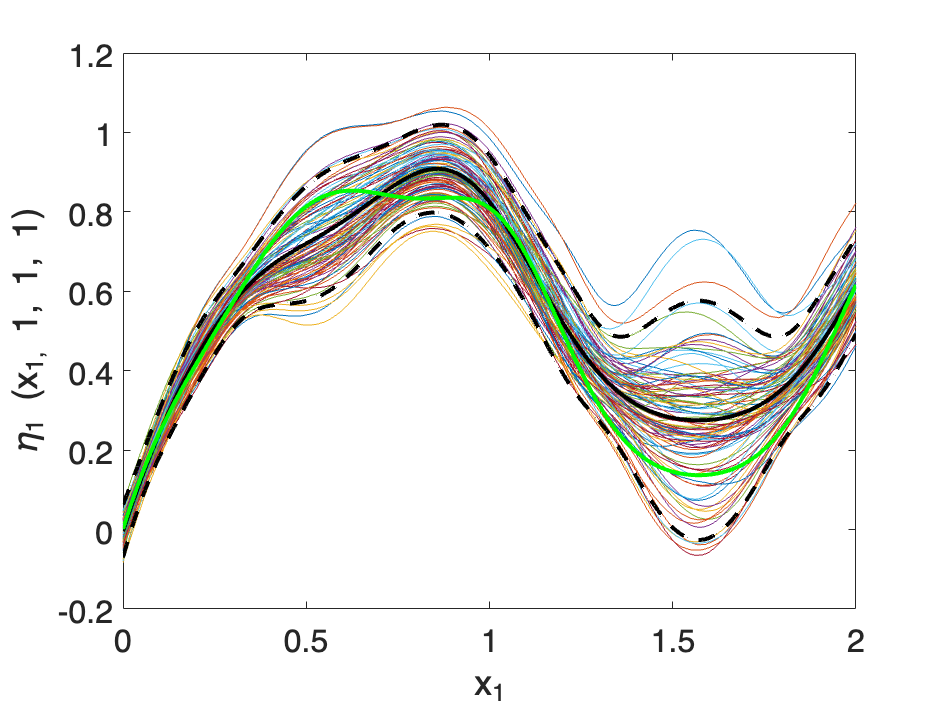

set(ah,'fontsize',16)
hold off


figure;
plot(fLocsPred(:,1), samples(:,:,2))
hold on
plot(fLocsPred(:,1), muLs(:,2), 'k', 'LineWidth',2)
hold on
plot(fLocsPred(:,1), muLs(:,2) - 1.96*(sqrt(sigma2Ls(:,2))), '--k', 'LineWidth',2)
hold on
plot(fLocsPred(:,1), muLs(:,2) + 1.96*(sqrt(sigma2Ls(:,2))), '--k', 'LineWidth',2)
hold on
plot(fLocsPred(:,1), gOutputTest(:,2), 'g', 'LineWidth',2)
xlabel('x_1')
ylabel('\eta_2 (x_1, 1, 1, 1)')
ah=gca;

ah =   Axes with properties:

             XLim: [0 2]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


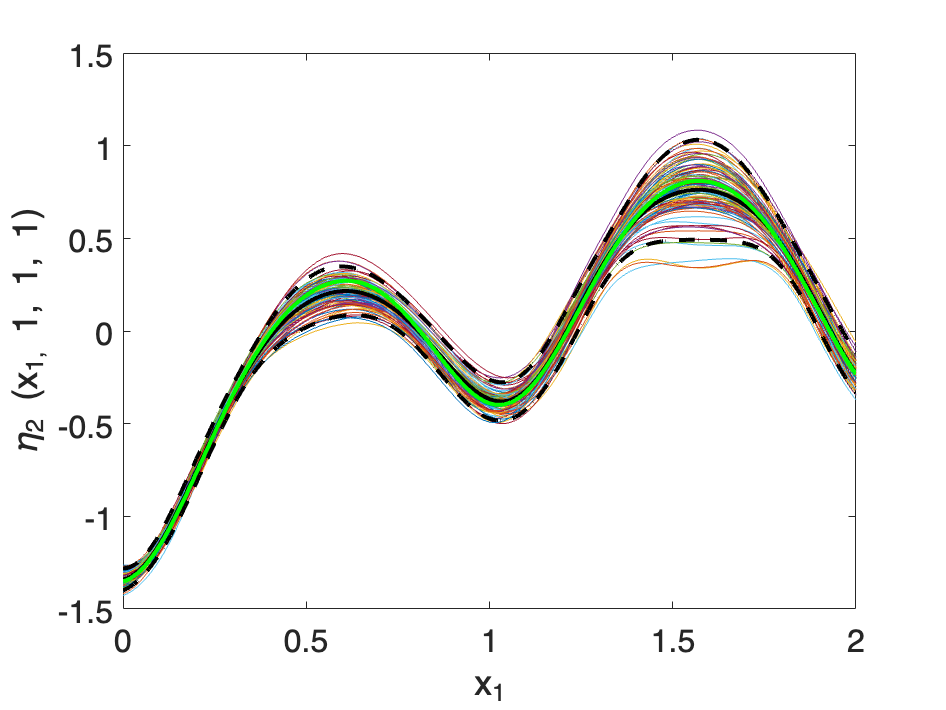

set(ah,'fontsize',16)
hold off

Next, we are moving to an example using imported data with a very large number of outputs for the first layer. This data is from a two-permeability coupled fluid flow and mechanical deformation Terzaghi consolidation problem. 

We will follow the same workflow but import the data instead of generating it. We will use PCA to determine our principal components for the output of $f$/ input to $g$ before continuing with the problem as the PPE would struggle with such high-dimensional input.

Here we'll only evalute the mean and variance of the PPLE for pressue -- both are functions of space. Below we have leave-one-out experiments with visualize after.

% Data for experiment
load Fig7data.mat

tVal = 100; % Number of design runs

fInputs = xxall;
zInputs = yyall;
gall = gall(:,2:end);
fall = fall(:,2:end);
nc = size(gall,2);

% Design input
gOutput = gall(1:tVal,:); % Pressure values
fOutputAll = fall(1:tVal,:); % Porosity Values

gtrue=gall(tVal+1:end,:);

fLocs = fInputs(1:tVal,:); % Input to the inside emulator (f)
zLocs = zInputs(1:tVal,:); % Input to the outside emulator (g)

%Perform pca on the data to determine relevant inputs
[z, num_modes, total_var_z] = pca_calculation(fOutputAll, 0);
fOutput = z; 
gLocs = [fOutput, zLocs];

%Predicting each of the pressure curves from the testing inputs.
tst = (size(gall,1)-tVal); %number of LOO experiments to perform
g = size(gOutput,2); %number of output variables
saveMus = zeros(g, tst);
saveSigs = zeros(g, tst);

trend = 'linear';
kernel = "pow_exp";

%building f and g models since they won't change each iteration
[fModels, gModel] = buildModels(fLocs, fOutput, gLocs, gOutput, trend, kernel);

The upper bounds of the range parameters are 6.624895 6.615050 6.712653 6.543199 Inf 
The initial values of range parameters are 0.132498 0.132301 0.134253 0.130864 
Start of the optimization 1: 
Elapsed time is 1.936323 seconds.
The number of interation is 40 
The number of function evaluation is 43 
The log marginal posterior is 336.884116 
The optimized range parameters are 0.414370 1.205493 5.997445 6.543185 
The optimized nugget parameter is 0.000000 
Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 4.000000e+01.

model = struct with fields:
                 input: [100×4 double]
                output: [100×1 double]
               num_obs: 100
                     k: 1
                     p: 4
                     X: [100×5 double]
             zero_mean: 0
                     q: 5
                nugget: 0
            nugget_est: 1
             range_par: []
          prior_choice: "ref_approx"
                     a: 0.2000
                     b: 1.3282
           kernel_type: [4×1 string]
                 alpha: [4×1 double]
           lower_bound: 1
              max_eval: 40
        initial_values: [2×5 double]
    num_initial_values: 2
       kernel_type_num: [4×1 double]
                    R0: [100×100×4 double]
                    CL: [4×1 double]
                    LB: [5×1 double]
              log_post: 336.8841


The initial values of range parameters are 0.786291 0.785122 0.796706 0.776594 
Start of the optimization 2: 
Elapsed time is 1.282930 seconds.
The number of interation is 38 
The number of function evaluation is 61 
The log marginal posterior is 336.884140 
The optimized range parameters are 0.414371 1.205496 5.997513 6.543195 
The optimized nugget parameter is 0.000000 
Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Optimization stopped because the relative changes in all elements of x are
less than options.StepTolerance = 1.000000e-05, and the relative maximum constraint
violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.

model = struct with fields:
                 input: [100×4 double]
                output: [100×1 double]
               num_obs: 100
                     k: 1
                     p: 4
                     X: [100×5 double]
             zero_mean: 0
                     q: 5
                nugget: 3.8042e-15
            nugget_est: 1
             range_par: []
          prior_choice: "ref_approx"
                     a: 0.2000
                     b: 1.3282
           kernel_type: [4×1 string]
                 alpha: [4×1 double]
           lower_bound: 1
              max_eval: 40
        initial_values: [2×5 double]
    num_initial_values: 2
       kernel_type_num: [4×1 double]
                    R0: [100×100×4 double]
                    CL: [4×1 double]
                    LB: [5×1 double]
              log_post: 336.8841
              beta_hat: [4×1 double]


The upper bounds of the range parameters are 6.624895 6.615050 6.712653 6.543199 Inf 
The initial values of range parameters are 0.132498 0.132301 0.134253 0.130864 
Start of the optimization 1: 
Elapsed time is 0.453828 seconds.
The number of interation is 20 
The number of function evaluation is 24 
The log marginal posterior is 248.529325 
The optimized range parameters are 0.406204 1.264514 5.077250 6.543199 
The optimized nugget parameter is 0.000000 
Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Optimization stopped because the relative changes in all elements of x are
less than options.StepTolerance = 1.000000e-05, and the relative maximum constraint
violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.

model = struct with fields:
                 input: [100×4 double]
                output: [100×1 double]
               num_obs: 100
                     k: 1
                     p: 4
                     X: [100×5 double]
             zero_mean: 0
                     q: 5
                nugget: 0
            nugget_est: 1
             range_par: []
          prior_choice: "ref_approx"
                     a: 0.2000
                     b: 1.3282
           kernel_type: [4×1 string]
                 alpha: [4×1 double]
           lower_bound: 1
              max_eval: 40
        initial_values: [2×5 double]
    num_initial_values: 2
       kernel_type_num: [4×1 double]
                    R0: [100×100×4 double]
                    CL: [4×1 double]
                    LB: [5×1 double]
              log_post: 248.5293


The initial values of range parameters are 0.786291 0.785122 0.796706 0.776594 
Start of the optimization 2: 
Elapsed time is 0.421152 seconds.
The number of interation is 18 
The number of function evaluation is 23 
The log marginal posterior is 248.529325 
The optimized range parameters are 0.406204 1.264515 5.077243 6.543199 
The optimized nugget parameter is 0.000000 
Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Optimization stopped because the relative changes in all elements of x are
less than options.StepTolerance = 1.000000e-05, and the relative maximum constraint
violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.

model = struct with fields:
                 input: [100×4 double]
                output: [100×1 double]
               num_obs: 100
                     k: 1
                     p: 4
                     X: [100×5 double]
             zero_mean: 0
                     q: 5
                nugget: 2.4860e-07
            nugget_est: 1
             range_par: []
          prior_choice: "ref_approx"
                     a: 0.2000
                     b: 1.3282
           kernel_type: [4×1 string]
                 alpha: [4×1 double]
           lower_bound: 1
              max_eval: 40
        initial_values: [2×5 double]
    num_initial_values: 2
       kernel_type_num: [4×1 double]
                    R0: [100×100×4 double]
                    CL: [4×1 double]
                    LB: [5×1 double]
              log_post: 248.5293
              beta_hat: [4×1 double]


The upper bounds of the range parameters are 2943.618101 2943.618101 2893.174532 2888.874957 Inf 
The initial values of range parameters are 58.872362 58.872362 57.863491 57.777499 
Start of the optimization 1: 
Elapsed time is 0.942937 seconds.
The number of interation is 27 
The number of function evaluation is 41 
The log marginal posterior is -135750.578083 
The optimized range parameters are 3.235630 5.629444 0.469388 0.459457 
The optimized nugget parameter is 0.000000 
Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Optimization stopped because the relative changes in all elements of x are
less than options.StepTolerance = 1.000000e-05, and the relative maximum constraint
violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.

model = struct with fields:
                 input: [100×4 double]
                output: [100×101 double]
               num_obs: 100
                     k: 101
                     p: 4
                     X: [100×5 double]
             zero_mean: 0
                     q: 5
                nugget: 0
            nugget_est: 1
             range_par: []
          prior_choice: "ref_approx"
                     a: 0.2000
                     b: 1.3282
           kernel_type: [4×1 string]
                 alpha: [4×1 double]
           lower_bound: 1
              max_eval: 40
        initial_values: [2×5 double]
    num_initial_values: 2
       kernel_type_num: [4×1 double]
                    R0: [100×100×4 double]
                    CL: [4×1 double]
                    LB: [5×1 double]
              log_post: -1.3575e+05


The initial values of range parameters are 0.800000 0.800000 0.786291 0.785122 
Start of the optimization 2: 
Elapsed time is 0.649330 seconds.
The number of interation is 19 
The number of function evaluation is 26 
The log marginal posterior is -135750.578083 
The optimized range parameters are 3.235608 5.629418 0.469389 0.459457 
The optimized nugget parameter is 0.000000 
Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Optimization stopped because the relative changes in all elements of x are
less than options.StepTolerance = 1.000000e-05, and the relative maximum constraint
violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.

model = struct with fields:
                 input: [100×4 double]
                output: [100×101 double]
               num_obs: 100
                     k: 101
                     p: 4
                     X: [100×5 double]
             zero_mean: 0
                     q: 5
                nugget: 1.8341e-08
            nugget_est: 1
             range_par: []
          prior_choice: "ref_approx"
                     a: 0.2000
                     b: 1.3282
           kernel_type: [4×1 string]
                 alpha: [4×1 double]
           lower_bound: 1
              max_eval: 40
        initial_values: [2×5 double]
    num_initial_values: 2
       kernel_type_num: [4×1 double]
                    R0: [100×100×4 double]
                    CL: [4×1 double]
                    LB: [5×1 double]
              log_post: -1.3575e+05
              beta_hat: [4×1 double]


tic()
% for pp = 1:tst
%   fLocsPred = fInputs((tVal+pp),:); %testing data for inside emulator
%   zLocsPred = zInputs((tVal+pp),:); %testing data for the outside emulator
%   pp
% 
%   etaVal = 0.00001;
% 
%   [saveMus(:,pp), saveSigs(:,pp), lESamples] = linkedEmulatorFunction(fModels, gModel, fLocsPred, zLocsPred, trend, kernel, etaVal);
% 
% end

Visualization of the PPLE leave-one-out predictions for the Terzaghi cosolidation problem. 

Note, the columns of upside down with depth below the surface going up in the figure.

pp = 1

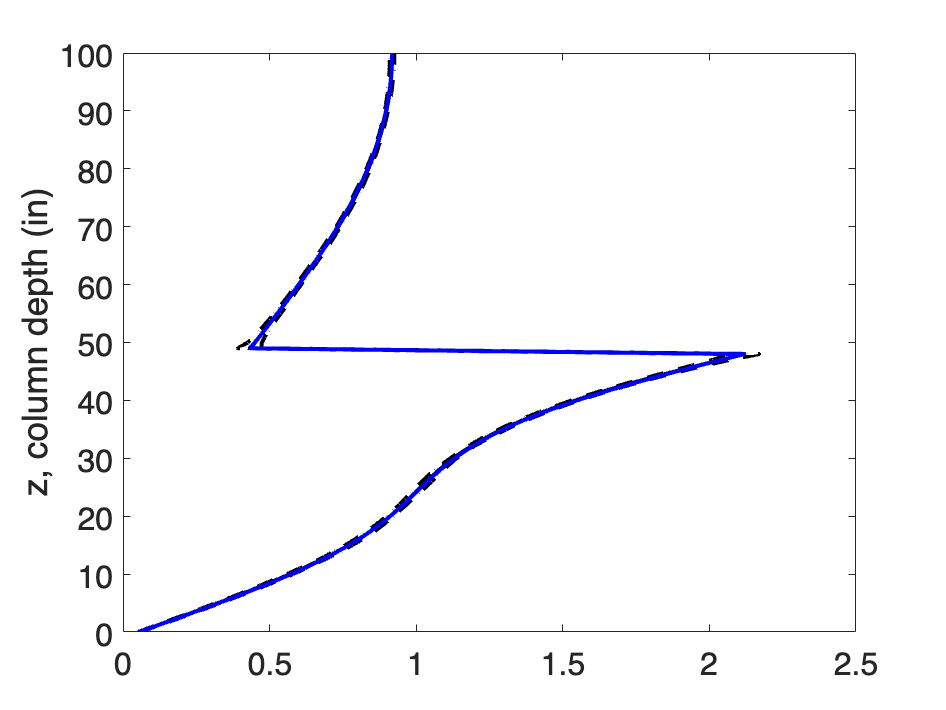

pp = 2

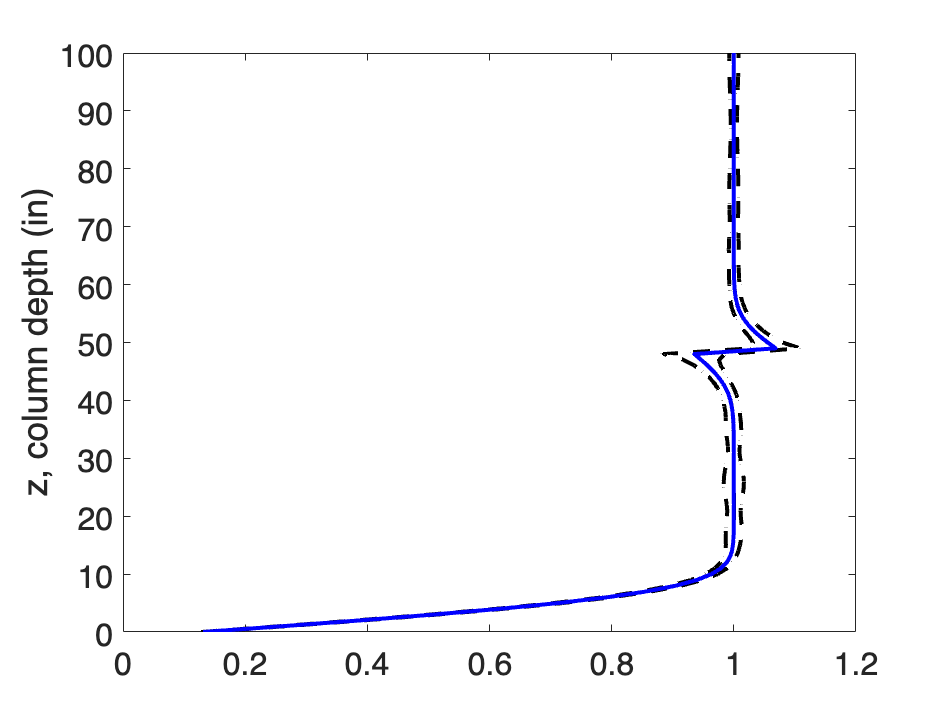

pp = 3

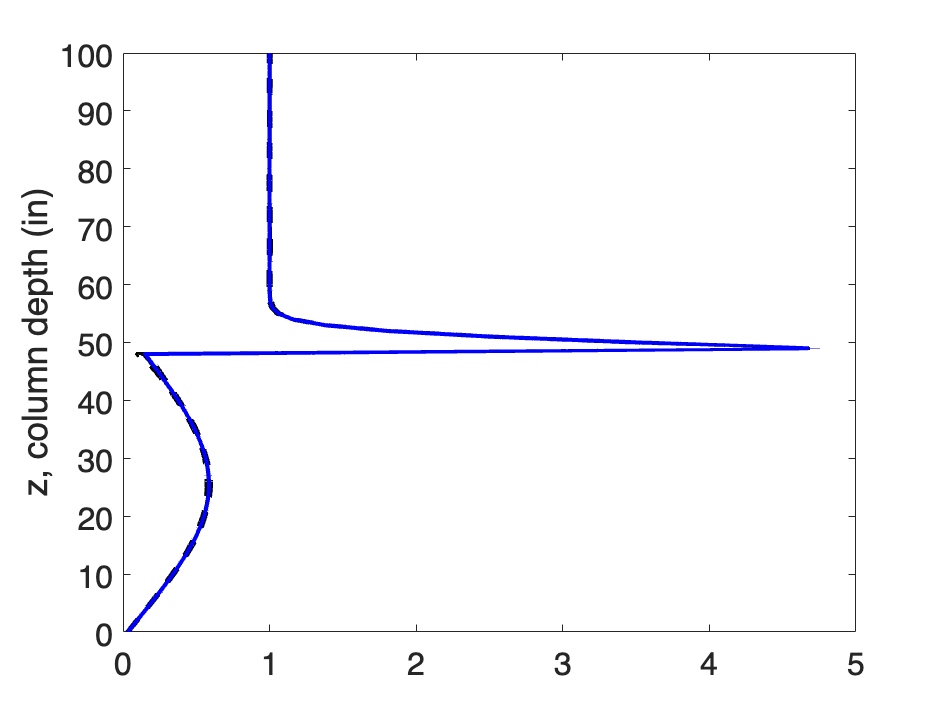

pp = 4

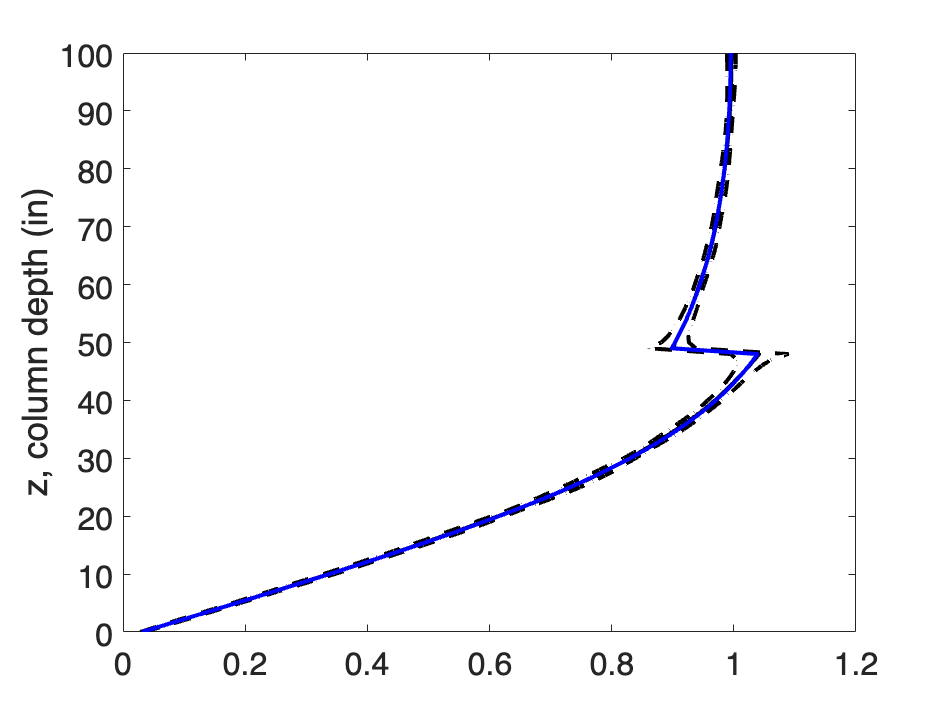

pp = 5

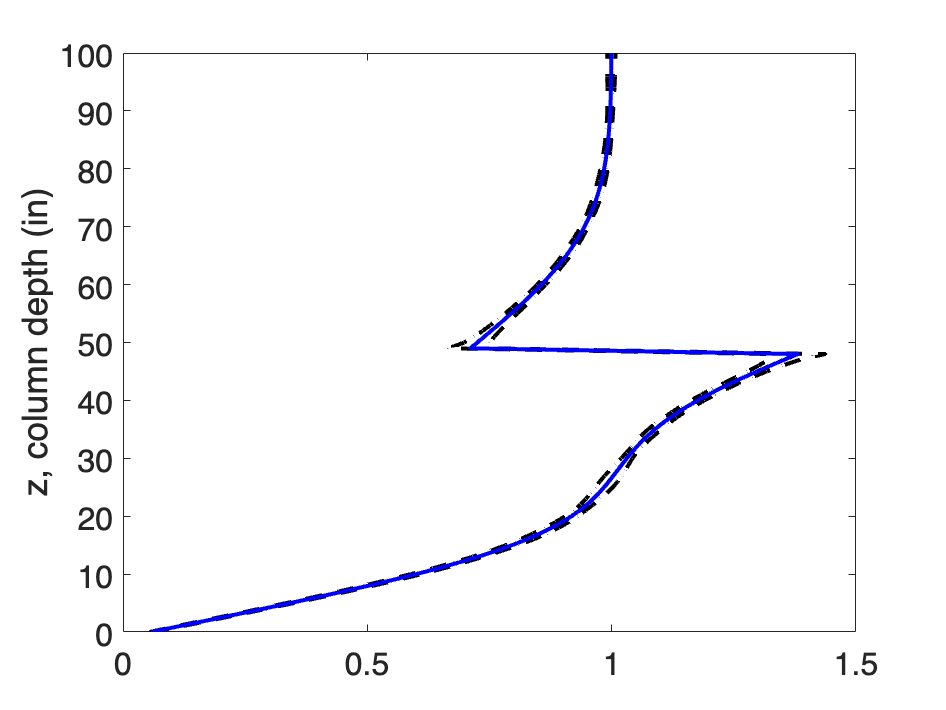

pp = 6

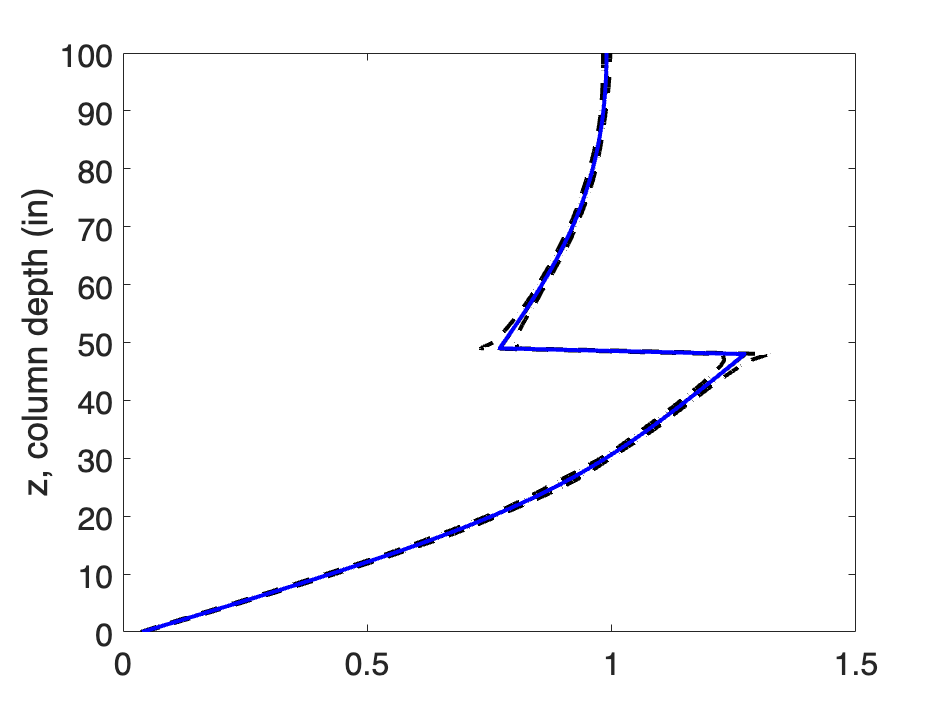

pp = 7

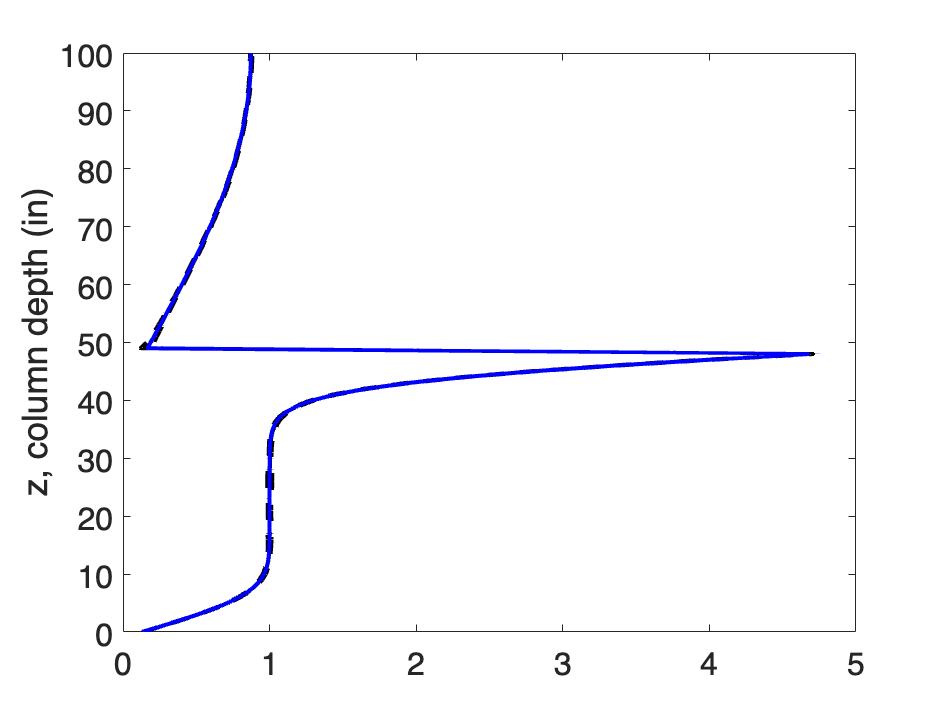

pp = 8

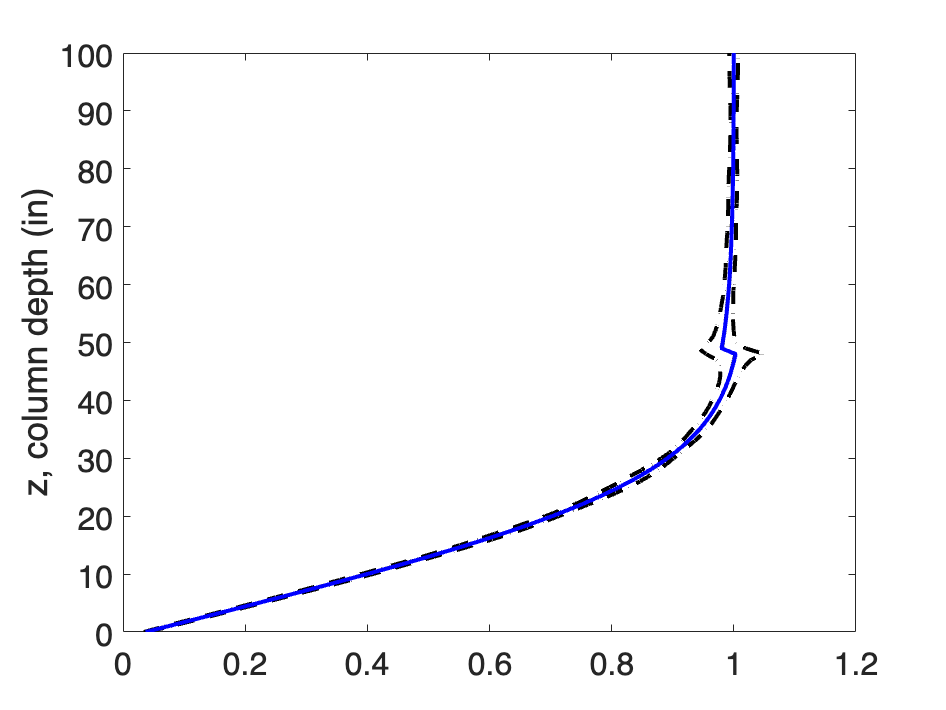

pp = 9

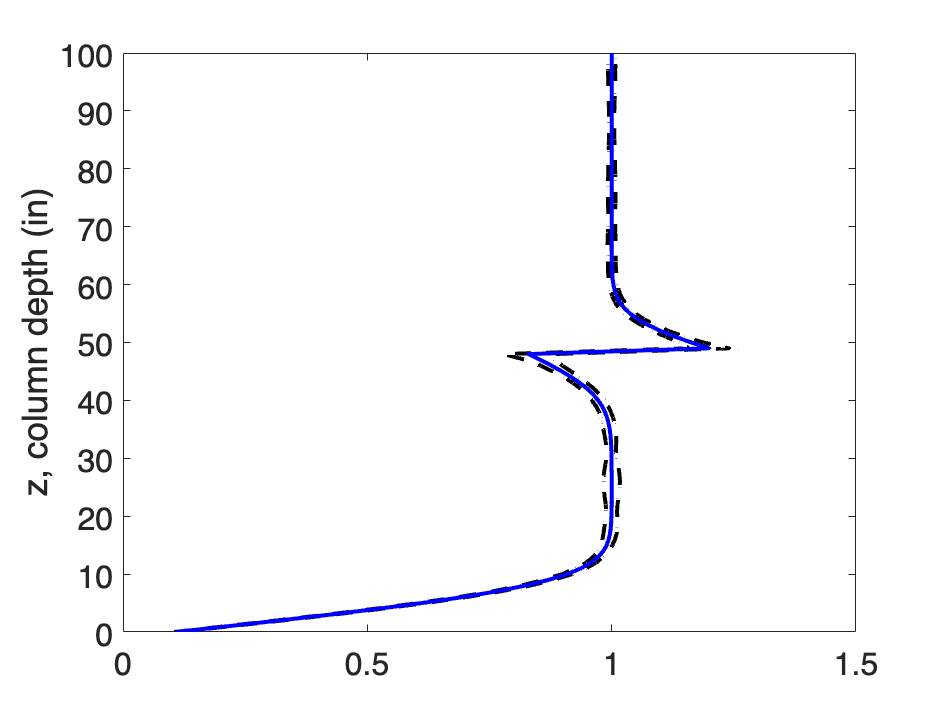

%zz=100:-1:0;%
zz=0:1:100; %spatial coordiante -- column depth
inds=1:1:101;
for pp=1:tst
pp    
figure; 
plot(saveMus(inds,pp),zz,'k','LineWidth',2)
hold on
plot(saveMus(inds,pp)+1.96*sqrt(saveSigs(inds,pp)),zz,'k--','LineWidth',2)
plot(saveMus(inds,pp)-1.96*sqrt(saveSigs(inds,pp)),zz,'k--','LineWidth',2)
plot(gtrue(pp,inds),zz,'b','LineWidth',2)
ylabel('z, column depth (in)')
zlabel('Pressure (psi *10^8')
ah=gca;
set(ah,'fontsize',16)
pause
hold off
end

toc()

Below we define the functions for the Linked Emulator, as well as a method to produce correlated samples, if desired. The 5 functions are fPrediction, gPrediction, buildModels, linkedSampling, and linkedEmulatorFunction.

There is also a PCA function included for the high-dimension example to reduce the dimensions of the output of $f$/ input to $g$

*fPrediction(fLocs, fOutput, fLocsPred, kernel)* - performs mean and standard deviation predictions from a parallel partial emulator for the given untested inputs based on the provided PPE model for *f*. 

**Inputs: **

fModel - A PPE model built using the RobustGaSP package. It contains an *n *x *m* matrix of design/training inputs and an *n *x *d* matrix of the corresponding outputs to the provided inputs (among other things) for the *f* emulator.

fLocsPred - An *N *x *m* matrix of untested inputs.

kernel - The name of the desired correlation function, defaults to Matern 5/2.

**Outputs:**

fPred - Predictive mean and standard deviation from the PPE ($$\tilde{f_i}$$) for the untested inputs provided (also includes upper and lower 95 values). 

***          

*gPrediction(gModel, gLocsPred, trend, kernel) *- performs mean and standard deviation predictions from a parallel partial emulator for the given untested inputs based on the provided PPE model for *g*.

**Inputs:** 

gModel - A PPE model built using the RobustGaSP package. It contains an $n \times (d+p)$ matrix (where $d$ is the number of outputs from $f$ and $p$ is the number of external inputs, $z$) of design/training inputs and an $n \times g$ matrix of the corresponding outputs to the provided inputs (among other things) for the $g$ emulator. \

gLocsPred - An *N *x *(d+p)* matrix of untested inputs where *d *is the number of outputs from *f* and *p* is the number of external inputs, *z*.

trend - The name of the specified trend of the data. Could be linear or constant, defaults to linear.

kernel - The name of the desired correlation function, defaults to Matern 5/2.

**Outputs:**

gPred - Predictive mean and standard deviation from the PPE ($$\tilde{g}$$) for the untested inputs provided (also includes upper and lower 95 values).   

***

*linkedSampling(fLocsPred, gLocsPred, muLs, sigma2Ls, fGamma, gGamma, N, gPred)* - performs linked sampling for the using the resulting values calculated from the parallel partial and linked emulators. This function is called inside of the separate linked emulator functions for the different cases with single or multiple outputs along with constant or linear trend. 

**Inputs:** 

fLocsPred - *N* x *m* matrix of untested inputs. 

gLocsPred - *N* x *(d+p)* matrix of untested inputs where *d* is the number of outputs from *f* and *p* is the number of external inputs, *z*. 

muLs - The *N* mean predictions from the linked emulator for the output of interest. 

sigma2Ls - The *N* variance predictions from the linked emulator for the output of interest. 

fGamma - The range parameters of the inputs from the $\tilde{f}$ emulators. 

gGamma - The range parameters of the inputs from the $\tilde{g}$ emulator. 

N - The number of testing points. 

gPred - The predictive mean from the PPE for *g*. 

**Outputs:**

A - The *N *x* N* covariance matrix. The predictive variance of the linked emulator is later extracted from its diagonal. 

samples - An *N *x* 100* matrix of correlated samples. 

*** 

*buildModels(fLocs, fOutput, gLocs, gOutput, trend, kernel)* - A function which takes in all of the design/training data and builds PPE models. An individual model ($$f_i$$) is constructed for each of the outputs in the *f* layer to improve predictions. If the size of the given design is large enough, the function will switch to using the Nelder-Mead optimization method, as suggested by the RobustGaSP package. 

**Inputs:**

fLocs - An *n* x *m* matrix of design/training inputs for the *f* emulator. 

fOutput - An *n* x *d* matrix of the corresponding outputs to the provided inputs. 

gLocs - An *n* x *(d+p)* matrix of design/training inputs for the *g* emulator. To give correct results, the external *z* inputs must concatenated with the true outputs from the function/model that the *f* layer emulates in the order: [fOutput, z]. 

gOutput - An *n* x *g* matrix of the corresponding outputs to the provided inputs. 

trend - The name of the specified trend of the data. Could be linear or constant, defaults to linear. 

kernel - The name of the desired correlation function, defaults to Matern 5/2. 

**Outputs:**

fModels - A list of PPE models built using the RobustGaSP package. Each model contains an *n* x *m* matrix of design/training inputs and an *n* x *d* matrix of the corresponding outputs to the provided inputs (among other things) for the corresponding $f_i$ emulator. Each individual $f_i$ model can be accessed using fModels(i). 

gModel - A PPE model built using the RobustGaSP package. It contains an *n* x *(d+p)* matrix (where *d* is the number of outputs from *f* and *p* is the number of external inputs, *z*) of design/training inputs and an *n* x *g* matrix of the corresponding outputs to the provided inputs (among other things) for the *g* emulator. 

***

*linkedEmulatorFunction(fModels, gModel, fLocsPred, zLocsPred, trend, kernel, eta)* - The function that takes in all of the PPE models and testing data and runs the whole linked emulator. It provides mean and variance predictions, as well as correlated samples. 

**Inputs:**

fModels - A list of PPE models built using the RobustGaSP package. Each model contains an *n* x *m* matrix of design/training inputs and an *n* x *d* matrix of the corresponding outputs to the provided inputs (among other things) for the corresponding $f_i$ emulator. Each individual $f_i$ model can be accessed using fModels(i). 

gModel - A PPE model built using the RobustGaSP package. It contains an *n* x *(d+p)* matrix (where *d* is the number of outputs from *f* and *p* is the number of external inputs, *z*) of design/training inputs and an *n* x *g* matrix of the corresponding outputs to the provided inputs (among other things) for the *g* emulator. 

fLocsPred - *N* x *m* matrix of untested inputs for the first layer, *f*. 

zLocsPred - *N* x *p* matrix of untested inputs for the *g* emulator. 

trend - The name of the specified trend, defaults to linear. 

kernel - The name of the desired correlation function, defaults to Matern 5/2. 

eta - Nugget term for regularizing R matrix during inversion, defaults to 1e-12.

**Outputs:**

means - The predictive mean(s) from the $\tilde{g}$ PPE. 

vars - The predictive variance(s) from the linked emulator. 

samples - An *N* x *100* matrix of correlated samples. 

function fPred = fPrediction(fModel, fLocsPred)
    numTest = size(fLocsPred, 1);
    testTrendMat = [fLocsPred ones(numTest,1)];
    
    optionsPred.testing_trend = testTrendMat; 
    fPred = predict_ppgasp(fModel,fLocsPred, optionsPred);
    
end

function gPred = gPrediction(gModel, gLocsPred, trend)

    numTest = size(gLocsPred,1);
	
    if(trend == "constant")
        testTrendMat = ones(numTest,1);
    else 
        testTrendMat = [gLocsPred, ones(numTest,1)];
    end
    
    optionsPred.testing_trend = testTrendMat;
	gPred = predict_ppgasp(gModel,gLocsPred, optionsPred);
  
end

function [fModels, gModel] = buildModels(fLocs, fOutput, gLocs, gOutput, trend, kernel)

	%we build the f model first
	m = size(fLocs, 1);
    fTrendMat = [fLocs ones(m,1)]; %the trend always be this way for f
    
	dim_io_f = size(fLocs,2);
    optionsf.trend=fTrendMat;
    optionsf.zero_mean = false; 
    optionsf.nugget_est = true;
	
	M = size(gLocs,1);
    if(trend == "constant")
        gTrendMat = ones(M,1);
    else
        gTrendMat = [gLocs, ones(M,1)];
    end 
	
    dim_io_g = size(gLocs,2);
    optionsg.trend=gTrendMat;
    optionsg.zero_mean = false; 
    optionsg.nugget_est = true;
	
    numF = size(fOutput,2);
	%an individual f emulator is created for each output component to improve
    %prediction accuracy
	for	i = 1:numF
		if (kernel == "sq_exp" || kernel == "pow_exp")
			alpha=2.0;
			optionsf.alpha=repmat(alpha,dim_io_f,1);
			optionsf.kernel_type=repmat("pow_exp",dim_io_f,1);
		elseif (kernel == "mat32" || kernel == "matern_3_2")
			optionsf.kernel_type=repmat("matern_3_2",dim_io_f,1);
		else
			optionsf.kernel_type=repmat("matern_5_2",dim_io_f,1);
		end
		fModels(i) = ppgasp(fLocs, fOutput(:,i), optionsf);
	end
	
	if (kernel == "sq_exp" || kernel == "pow_exp")
		alpha=2.0;
		optionsg.alpha=repmat(alpha,dim_io_g,1);
		optionsg.kernel_type=repmat("pow_exp",dim_io_g,1);
	elseif (kernel == "mat32" || kernel == "matern_3_2")
		optionsg.kernel_type=repmat("matern_3_2",dim_io_g,1);
	else
		optionsg.kernel_type=repmat("matern_5_2",dim_io_g,1);
	end
	gModel = ppgasp(gLocs, gOutput, optionsg); %ppgasp for g layer
end

function samples = linkedSampling(fLocsPred, gLocsPred, muLs, sigma2Ls, fGamma, gGamma, N, gPred)

    A = ones(N);
    numFCols = size(fLocsPred,2);
    numGCols = size(gLocsPred,2);

    for i = 1:N
        for j = 1:N
            if(i == j)
                A(i,j) = sigma2Ls(i);
            else 
                rho_f = 1;
                for k = 1:numFCols
                    if (size(fLocsPred,1) > 1)
                        rho_f = rho_f * cKSingle(fLocsPred(i,k),fLocsPred(j,k),fGamma(k));
                    else
                        rho_f = rho_f * cKSingle(fLocsPred(k),fLocsPred(k),fGamma(k));
                    end
                end
                tempSig = sqrt(sigma2Ls(i) - 2*rho_f*sqrt(sigma2Ls(i))*sqrt(sigma2Ls(j)) + sigma2Ls(j));
                rho_eta = 1;
                for k = 1:numGCols
                    rho_eta = rho_eta * xiSingle(muLs(i), tempSig, gGamma(k), muLs(j));
                end
                A(i,j) = sqrt(sigma2Ls(i))*sqrt(sigma2Ls(j))*rho_eta*rho_f;
            end
        end
    end
    L = chol(A + eye(N)*0.0000000001);
    L = L';
    samples = zeros(N, 100);
    for i = 1:100 
        u = normrnd(0,1,[N,1]);
        ysamp = gPred + L*u;
        samples(:,i) = ysamp;
    end
end

function [gPredMean, samplesA, samples] = linkedEmulatorFunction(fModels, gModel, fLocsPred, zLocsPred, trend, kernel, eta)

    rng(9)
    N = size(fLocsPred,1);
    numFInputs = size(fModels(1).input, 2);
    numFOutputs = length(fModels);
    ygpVals = zeros(N, numFOutputs);
    sdVals = zeros(N, numFOutputs);
    gammas = zeros(numFOutputs, numFInputs);
    fGamma = ones(numFInputs,1);
    %first layer PPE - take in f^D inputs/outputs, take in f^* inputs
    for jj = 1:numFOutputs
        fPred = fPrediction(fModels(jj), fLocsPred);

        ygp = fPred.mean;
        v = fPred.sd;
        ygpVals(:,jj) = ygp;
        sdVals(:,jj) = v;
        gammas(jj,:) = fModels(jj).range_par;
        for jjj = 1:numFInputs
            fGamma(jjj) = fGamma(jjj)*gammas(jj,jjj);
        end
    end
    
    fPred.mean = ygpVals;
    fPred.sd = sdVals;

    %second layer PPE (to get range parameters) - take in g^D inputs/outputs, take in g^* inputs = first layer ppe outputs + second layer exogenous inputs
    gLocs = gModel.input;

    gLocsPred = [fPred.mean zLocsPred];


    %g layer - all inputs and outputs are imported - might want to consider how that will look
    %train inputs are called gLocs, train outputs are called gOutput, test inputs are called fLocsPred
    gPred = gPrediction(gModel, gLocsPred, trend);
    gPredMean = gPred.mean;
    %based on trend call one of two functions for the linked emulator
    muVec = fPred.mean;
    sigVec = fPred.sd;

    %this is the setup for how we've been doing the linked emulator - need to know how many terms are in w, z (d and p) - either import that or be able to 
    d = size(muVec, 2);
    p = size(gLocs,2) - d;
    wT = gLocs(:,1:d);
    zT = gLocs(:,(d+1):(d+p));
    m = size(gLocs,1);
    gSigVec = gModel.sigma2_hat;
    gGamma = gModel.range_par;
	gOutput = gModel.output;

    addpath('matFuncs');
    if (kernel == "sq_exp" || kernel == "pow_exp")
        addpath('SE');
    elseif (kernel == "mat32" || kernel == "matern_3_2")
        addpath('Mat32');
    else
        addpath('Mat52');
    end


    %   c_k = array(0, dim = c(m, m, (d+p)))
    c_k = zeros(m,m,(d+p));
    for i = 1:m
        for j = 1:m
            for k = 1:(d+p)
                c_k(i,j,k) = cKSingle(gLocs(i,k), gLocs(j,k), gGamma(k));
            end
        end
    end

    for k = 1:(d+p)
        if k == 1
            R = c_k(:,:,k);
        else
            R = R .* c_k(:,:,k);
        end
    end

    temp = diag(size(R,1));
    temp = temp*eta;
    rInv = inv(R + temp);
    g = size(gOutput,2); %number of outputs we are interested in
    numTest = size(gLocsPred,1);
    addpath('linkedCases'); 
    if g == 1
        if trend == "constant"
            [samplesA, samples] = linkedConstantSingle(m, d, p, g, numTest, wT, zT, fLocsPred, fGamma, gLocsPred, gPred, gOutput, gGamma, muVec, sigVec, gSigVec, rInv, eta);
        else
            [samplesA, samples] = linkedLinearSingle(m, d, p, g, numTest, wT, zT, fLocsPred, fGamma, gLocsPred, gPred, gOutput, gGamma, muVec, sigVec, gSigVec, rInv, eta);
        end
    else
        if trend == "constant"
            [samplesA, samples] = linkedConstantMultiple(m, d, p, g, numTest, wT, zT, fLocsPred, fGamma, gLocsPred, gPred, gOutput, gGamma, muVec, sigVec, gSigVec, rInv, eta);
        else
            [samplesA, samples] = linkedLinearMultiple(m, d, p, g, numTest, wT, zT, fLocsPred, fGamma, gLocsPred, gPred, gOutput, gGamma, muVec, sigVec, gSigVec, rInv, eta);
        end
    end
end

% pca_calculation function performs Principal Component Analysis on the given data 
% and returns the principal components based on the user-defined number of modes.
function [z, num_modes, total_var_z] = pca_calculation(data, user_modes)

    % Compute the mean of each column (feature) in the data.
    Xbar = mean(data, 1);
    
    % Center the data by subtracting the mean.
    X = (data - Xbar)';

    % Calculate the covariance matrix A.
    A = X * X';
    
    % Compute the Singular Value Decomposition (SVD) of the centered data.
    [E, D, V] = svd(X);
    P = E';
    
    % Check if the user specified the number of modes.
    if user_modes ~= 0
        num_modes = user_modes;
        total_var_z = 0;
    else 
        % If not specified, compute the principal components.
        z = (P * X)';
        
        % Compute the variance of each principal component.
        var_z = var(z, 1);
        
        % Calculate the total variance.
        sum_var_z = sum(var_z);
        
        % Compute the percentage of variance explained by each mode.
        total_var_z = (var_z ./ sum_var_z) * 100;
      
        % Retain the number of modes required to explain at least 95% of the total variance.
        for i = 1:10
            if sum(total_var_z(1:i)) >= 90
                break;
            end
        end
        num_modes = i;
    end

    % Retain only the first num_modes principal components.
    P = P(1:num_modes, :);
    z = (P * X)';
    
    % Normalize the retained principal components to be in the range [0, 1].
    x0 = 0; x1 = 1;
    for p = 1:num_modes
        z_ub = max(z(:, p));
        z_lb = min(z(:, p));
        z_norm = (x1 - x0) .* (z(:, p) - z_lb) ./ (z_ub - z_lb) + x0;
        temp(:, p) = z_norm';
    end
    
    z = temp;
end